# MAT188 - Topic 2 Assignment

Please ensure you upload both MLX and PDF files to Gradescope.

## Introduction

For this assignment we will be looking at the two-link robotic arm shown in Figure 1 and the animation below. The first link rotates around the origin and the second link rotates around the end of the first link.

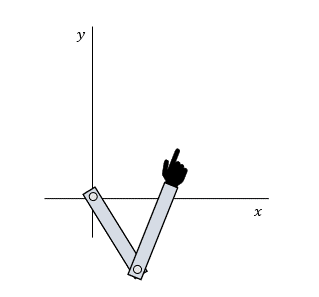

You will be given the lengths of the links $L_1$ and $L_2$, as well as their angles relative to the horizontal axis $\theta_1$ and $\theta_2$. Using this information, the goal is to calculate the x,y-coordinates of the hand at the end of the second link as shown in Figure 1c.

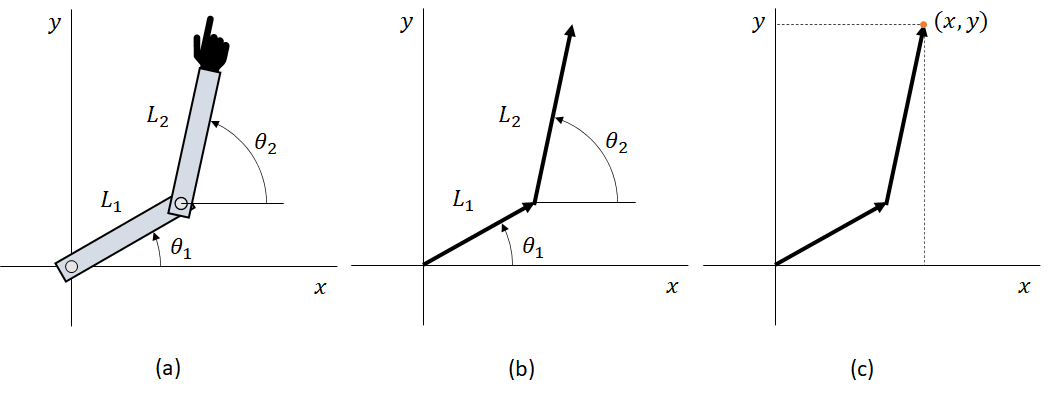

**Figure 1:** (a) diagram of the two-link robotic arm (b) simplified diagram - each arrow represents one of the links (c) x,y-coordinates of the hand (to be calculated)

This assignment consists of four parts. In each of the parts, you will

- Part 1: load data from a CSV file and visualize the provided data

- Part 2: write a function to calculate the x and y displacement of a single link given its length and angle

- Part 3: compute the x,y-coordinates of the hand using the function from Part 2

- Part 4: use spanning sets to determine if the robotic arm can reach certain locations within the *x-y* plane

## Part 1: Load and Visualize Data

The first step is to load the data from the CSV file into the workspace and to define variables for the lengths of the two links.

The data is provided to you in `https://raw.githubusercontent.com/dtxe/mat188_datasets/main/robot_trajectory.csv`. This file contains the values of  $\theta_1$ and $\theta_2$ at different points in time. The first column contains the values of $\theta_1$ **in degrees** and is labelled `theta1`. The second column contains the values of $\theta_2$ **in degrees** and is labelled `theta2`. Each entry (row) in this table corresponds to the angles at a different point in time.

### 1.1 Define variables for the lengths of the two links

The lengths of the two links are $L_1 =L_2 =10\;\textrm{cm}$. Variables `L1` and `L2` representing the lengths of the links are defined below. You do not need to do anything for this part.

L1 = 10; % length of the first link in cm
L2 = 10; % length of the second link in c

### 1.2 Load data from the CSV file provided

Import data from the CSV file provided** as a table** to a variable called `data`. Recall that in the lab exercise, you used `readtable` to import data from a CSV on the internet using its URL.

data = readtable('https://raw.githubusercontent.com/dtxe/mat188_datasets/main/robot_trajectory.csv');

% show the first few rows to see if we loaded it properly
first_rows_data = head(data);
disp(first_rows_data);

    theta1    theta2
    ______    ______

    131.55    231.57
    137.97    234.59
    136.21    233.22
    136.89    240.27
    136.77    247.19
    137.28    254.34
    138.74    261.92
    141.28    270.07



### 1.3 Make a polar plot to visualize the trajectory of the first link

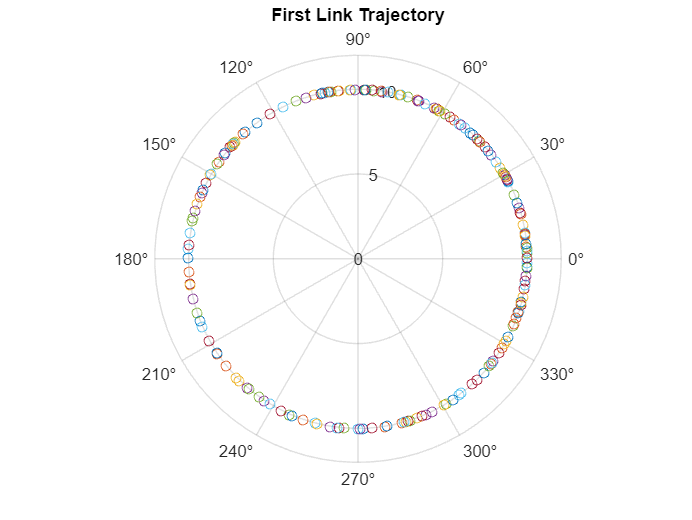

polarscatter(deg2rad(data.theta1),L1) %polar scatters the trajectory
title('First Link Trajectory')

## Part 2: Forward Kinematics of the Two-Link Robot

Almost there! For this last part, you will compute the x,y-coordinates of the hand at the end of the second link, update your data table, and visualize your results.

### 2.1. Compute the x,y-coordinates and update your table

First, use the angles $\theta_1$ and $\theta_2$ in `data` (the table you loaded in Part 1) and the function you wrote in Part 2 to find the x,y-coordinates of the hand for each entry in `data`. Then, update the table `data` by adding two columns to store the x and y coordinates that you computed. Make sure to display the updated table to demonstrate that you have done this successfully.

**Hint: **To calculate the location of the hand, you can calculate the displacements of the two links individually (Figure 3a) and then take the sum (Figure 3b). 

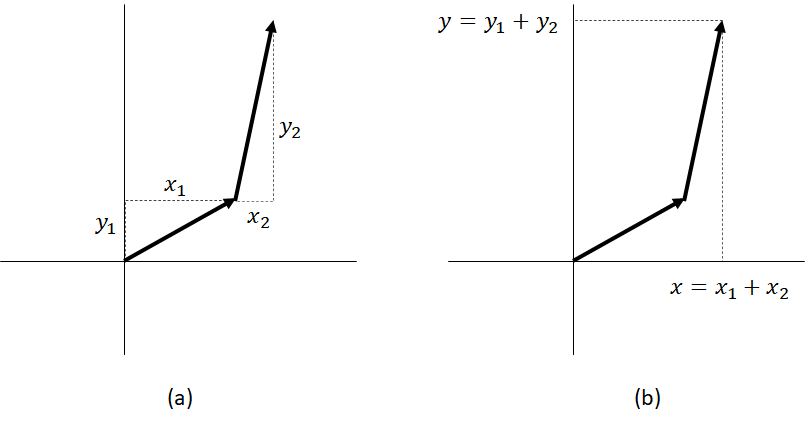

**Figure 3:** (a) displacements of individual links (b) total displacement of both links

**Please write your code below.**

% ---- YOUR CODE HERE ----
[x1,y1] = add_displacements(data.theta1, L1); %add_displacement function for first link's displacement
[x2,y2] = add_displacements(data.theta2, L2); %add_displacement function for second link's displacement
data.x = x1 + x2; %adding new "x" column to table that holds x-direction displacement
data.y = y1 + y2; %adding new "y" column to table that holds y-direction displacement

### 2.2. Plot the trajectory

Plot your x and y coordinates to draw a picture.

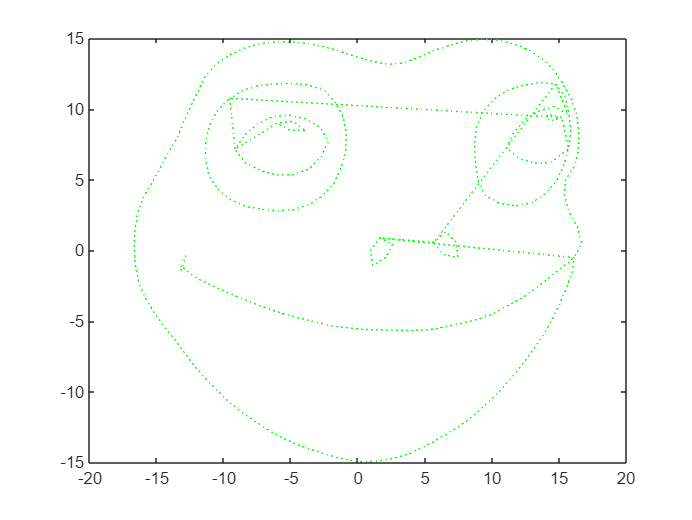

% ---- YOUR CODE HERE ----
plot(data.x, data.y, "g:") %plotting x and y displacements

## Part 3: Linear Combinations and Spanning Sets

### 3.1 Basis Vectors and Linear Combinations

Write a function that takes in two 3D vectors and returns the following:

- true, if the two vectors are linearly independent

- false, if the two vectors are linearly dependent

% your code here
% code is listed in functions below

### 3.2 Case Palletizer Robot

Atlas Robots is an engineering firm that happens to employ recent UofT graduates with fond memories of MAT188, CIV100 and APS111/112. Atlas was contracted to improve the production workflow for one of their clients who wanted to automate case pallet stacking and storage. The final recommendation was the KUKA case palletizer robot.

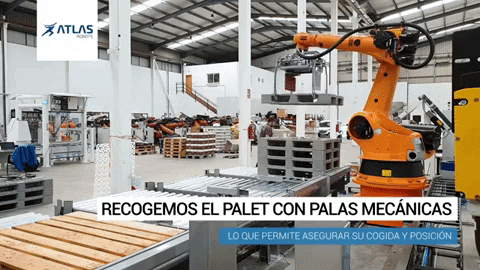

*Image caption: A KUKA case palletizer robot with mobile track (image source: *[*atlas_robots*](https://atlas-robots.com/en/portfolio/robot-paletizador-track-movil-puratos/)*). *

As observed in the gif image above, the robot has several actuators(*) and is mounted on a horizontal mobile track that extends its range of movement to different workstations. Note that the sequence of actuators  is not important. The focus is rather on the combination of movements required to effect a desired motion.

(* *An actuator is a device that requires a source of energy e.g., electrical, hydraulic pressure or pneumatic pressure to move part of a mechanism*)

Now consider that some modifications were made to the KUKA robot such that the 

- when actuator 1 is activated, the pallet moves along a line described by the vector $\vec{\;a} =\left\lbrack \begin{array}{c}
0\ldotp 75\\
0\\
0\ldotp 25
\end{array}\right\rbrack t$

- when actuator 2 is activated, the pallet moves along a line described by the vector $\vec{\;b} =\left\lbrack \begin{array}{c}
0\ldotp 45\\
0\ldotp 45\\
0\ldotp 45
\end{array}\right\rbrack t$ 

- when actuator 3 is activated, the pallet moves along a line described by the vector $\vec{\;c} =\left\lbrack \begin{array}{c}
0\ldotp 75\\
0\\
0
\end{array}\right\rbrack t$

- when actuator 4 is activated, the pallet moves along a line described by the vector $\vec{\;d} =\left\lbrack \begin{array}{c}
0\ldotp 75\\
0\ldotp 25\\
0
\end{array}\right\rbrack t$

                        for arbitrary parameter $t$.

Find basis vectors that span the robot's resulting range of motion if:

- all the actuators are working?

% your code here
%defining a, b, c, and d actuators 
a = [0.75        
    0
    0.25];
b = [0.45
    0.45
    0.45];
c = [0.75
    0
    0];
d = [0.75
    0.25
    0];
%defining basis vectors
b1_allactuator = [];
b2_allactuator = [];
b3_allactuator = [];
b4_allactuator = [];
[a,b,c,d]

ans =     0.7500    0.4500    0.7500    0.7500
         0    0.4500         0    0.2500
    0.2500    0.4500         0         0


%A = rref([a,b,c,d])    %row reducing matrix made of all actuators
if rank(A) == 4         %if rank(A) is 4, then all 4 actuators make the basis
    b1_allactuator = a
    b2_allactuator = b
    b3_allactuator = c
    b4_allactuator = d
elseif rank(A) == 3    %if rank(A) is 3, then the first 3 actuators make the basis
    b1_allactuator = a
    b2_allactuator = b
    b3_allactuator = c
elseif rank(A) == 2    %if rank(A) is 2, then the first 2 actuators make the basis
    b1_allactuator = a
    b2_allactuator = b
elseif rank(A) == 1    %if rank(A) is 1, then the first actuator make the basis 
    b1_allactuator = a
elseif rank(A) == 0    %no basis vectors
end

b1_allactuator =     0.7500
         0
    0.2500


- only actuator 1 and 4 are working?

% checking if actuator 1 and 4 work and finding the basis vectors 
if (is_lin_ind(a,d)) == true
    b1_actuator14 = a;
    b2_actuator14 = d;
end

- only actuator 2 and 3 are working?

% checking if actuator 2 and 3 work and finding the basis vectors 
if (is_lin_ind(b,c)) == true
    b1_actuator23 = b;
    b2_actuator23 = c;
end

Are there one or more actuators which, if failed, would still allow the robot to retain its range of motion?

% As long as there are three actuators present, the robot will be able to
% maintain its range of motion. Since the range of motion spans R3, there
% only need to be 3 basis vectors that are a spanning set and are linearly
% independent. Therefore, any one of the actuators can fail and the robot
% will still be able to retain its range of motion. This can be shown
% through different matricies made of actuators a,b,c,d. If the matricies,
% when row reduced, have a rank of 3, then that means one actuator is
% linearly dependent on anotherm which means that if it fails it will not
% have any impact on the range of motion. This is shown below. 
A = rank(rref([a,b,c,d]))

A = 3

B = rank(rref([a,b,d,c]))

B = 3

C = rank(rref([a,b,c,d]))

C = 3

D = rank(rref([b,c,d,a]))

D = 3

E = rank(rref([c,d,a,b]))

E = 3

% Since the rank of all these matricies is 3, this means that any one of
% the actuators can fail and the robot can retain its motion. 

## Functions

Here you will put all functions you are asked to write in this assignment. In total, there are four functions required.

**Part 2.1**

Inputs:

- `theta` - a column vector (`N x 1`) containing the angles of the link in radians

- `rho` - a scalar, the length of the link

Outputs:

- `x` - a column vector (`N x 1`) containing x displacements of the link

- `y` - a column vector (`N x 1`) containing y displacements of the link

**Part 3.1**

Inputs:

- `vec1` - Any 3D vector.

- `vec2` - Any other 3D vector.

Output:

- `islind `- A logical output that is `true` if the vectors are linearly independent, and `false` if they are linearly dependent. 

**Put all functions in the code block below**

function [x,y] = add_displacements(theta, rho)  %function that computes the x and y displacements 
x = rho * cosd(theta);
y = rho * sind(theta);
end

function [vec] = is_lin_ind(v1,v2) %function that checks linear independency between 2 vectors. returns true if they are linearly indepedent and false otherwise.
s = rref([v1,v2]);
if rank(s) == 2
    vec = true;
else 
    vec = false;
end
end